# Inspection des donnees Netcdf brutes et reduites en 2D

clear; clc;
tic

## Definition des variables contextuelles

% pc = 'C:/Users/lehuen201/Melting_Potes_Amlh_Phd/';
pc = 'K:/BOREA/Melting Potes/Melting_Potes_Amlh_Phd/'; % 
tsk = 'A_SDM/';
site = 'ES'; % ES for Seine estuary

wdpath = [pc 'Melting Pot/',tsk]; 
wdworknc = [pc 'Melting Pot-A_SDM-Mars3D_Extract/']; %  site '/' % Emplacement de sauvegarde des matrices generees
wdmat = [wdpath,'Matrices/'];
wdres = [wdpath,'Resultats/'];
wdgraph = [wdpath,'Plots/HMS_Matlab/Inspection_Ncf/'];

etudenc = [site,'_Ncf']; 
etude = [site,'_Mars'];
an = [1990:2000 2005:2018]; ansauv = an; 

nc2d = load ([wdmat, etude, '_Nc2D']);

finesse = 100;
plot_reso='-r100';
save_plot=0;

## Lancement de la boucle

% idx=1;
for idx = 1:length(an)
anstr = num2str(an(idx));

## Variables 2D

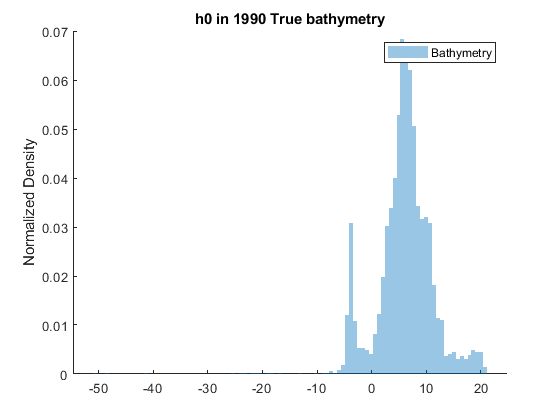

figure;clf;

x1=eval(['nc2d.bathy_' anstr]);
hold on
histogram(x1,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
title(sprintf('%s in %s %s','h0', anstr, nc2d.predict{9,2}));
ylabel('Normalized Density');
legend('Bathymetry')
hold off

### Variables 3D

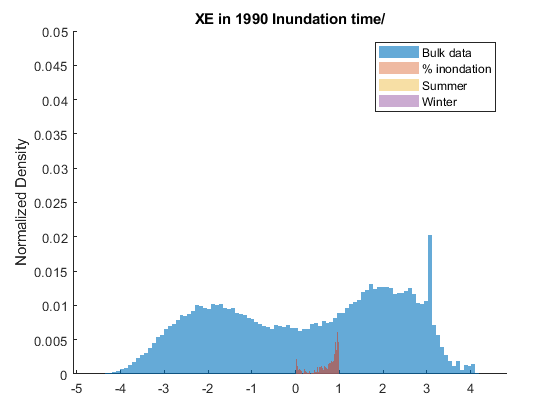

try load ([wdworknc,etudenc,'_Var3D_',anstr]);
figure;clf;
hold on; 
x=eval(['nc2d.' nc2d.predict{3,1} '_' anstr]);
xs=eval(['nc2d.' nc2d.predict{3,1} '_s' '_' anstr]);
xw=eval(['nc2d.' nc2d.predict{3,1} '_w' '_' anstr]);
histogram(Var3D.Hyd_XE,finesse,'EdgeColor','none','Normalization','probability');
ylim([0 0.05]);
title(sprintf('%s in %s %s/%s','XE', anstr, nc2d.predict{3,2}));
histogram(x,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xs,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xw,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
ylabel('Normalized Density');
legend('Bulk data','% inondation','Summer', 'Winter')
hold off
if save_plot==true; print(sprintf('%s%s_Insp_xe_%s', wdgraph,etude,anstr),'-dtiff',plot_reso); end


### Variables Sediments 3D

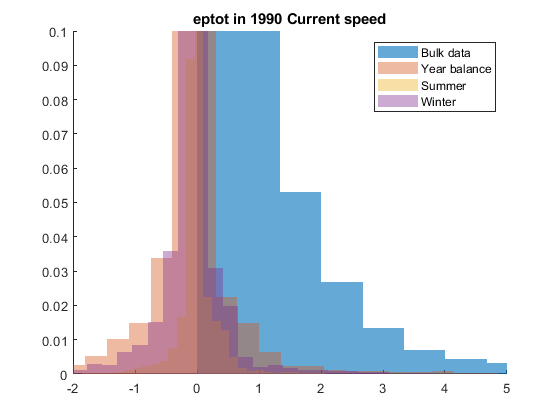

figure;clf;

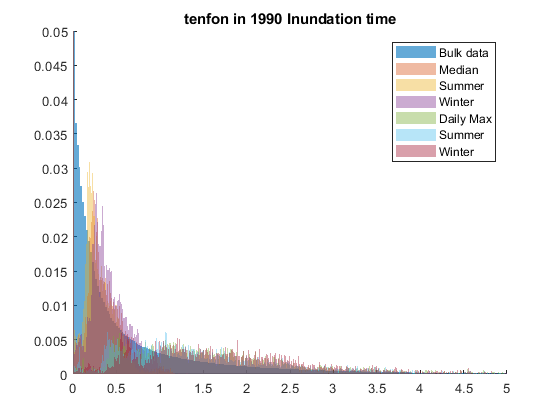

hold on;
x1=eval(['nc2d.' nc2d.predict{10,1} '_' anstr]);
x1s=eval(['nc2d.' nc2d.predict{10,1} '_s' '_' anstr]);
x1w=eval(['nc2d.' nc2d.predict{10,1} '_w' '_' anstr]);
histogram(Var3D.Sed_EPTOT,finesse,'EdgeColor','none','Normalization','probability');
title(sprintf('%s in %s %s','eptot', anstr, nc2d.predict{1,2}));
histogram(x1,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1s,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1w,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
legend('Bulk data','Year balance','Summer','Winter')
xlim([-2 5]); ylim([0 0.1]);
hold off
if save_plot==true; print(sprintf('%s%s_Insp_eptot_%s', wdgraph,etude,anstr),'-dtiff',plot_reso); end

figure;clf;

hold on;
x=eval(['nc2d.' nc2d.predict{11,1} '_' anstr]);
xs=eval(['nc2d.' nc2d.predict{11,1} '_s' '_' anstr]);
xw=eval(['nc2d.' nc2d.predict{11,1} '_w' '_' anstr]);
x1=eval(['nc2d.' nc2d.predict{12,1} '_' anstr]);
x1s=eval(['nc2d.' nc2d.predict{12,1} '_s' '_' anstr]);
x1w=eval(['nc2d.' nc2d.predict{12,1} '_w' '_' anstr]);
histogram(Var3D.Sed_TENFON,finesse*10,'EdgeColor','none','Normalization','probability');
title(sprintf('%s in %s %s','tenfon', anstr, nc2d.predict{3,2}));
histogram(x,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xs,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xw,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1,finesse*10,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1s,finesse*10,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1w,finesse*10,'facealpha',.4,'EdgeColor','none','Normalization','probability');
legend('Bulk data','Median','Summer','Winter','Daily Max','Summer','Winter')
xlim([0 5]); ylim([0 0.05]);
hold off
if save_plot==true; print(sprintf('%s%s_Insp_tenfon_%s', wdgraph,etude,anstr),'-dtiff',plot_reso); end
catch e
    fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
end % try à partir de base

### Variables Hydrologiques 4D

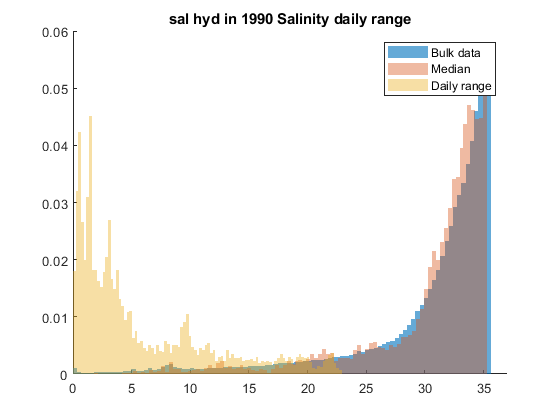

try load ([wdworknc,etudenc,'_Hyd_SAL_',anstr],'Hyd_SAL');
figure;clf;
hold on;
x=eval(['nc2d.' nc2d.predict{4,1} '_' anstr]);
x1=eval(['nc2d.' nc2d.predict{5,1} '_' anstr]);
histogram(Hyd_SAL,finesse,'EdgeColor','none','Normalization','probability');
title(sprintf('%s in %s %s','sal hyd', anstr, nc2d.predict{5,2}));
histogram(x,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
legend('Bulk data','Median','Daily range')
xlim([0 37]);
hold off
if save_plot==true; print(sprintf('%s%s_Insp_sal_hyd_%s', wdgraph,etude,anstr),'-dtiff',plot_reso); end
clear Hyd_SAL
catch e
    fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
end % try à partir de base

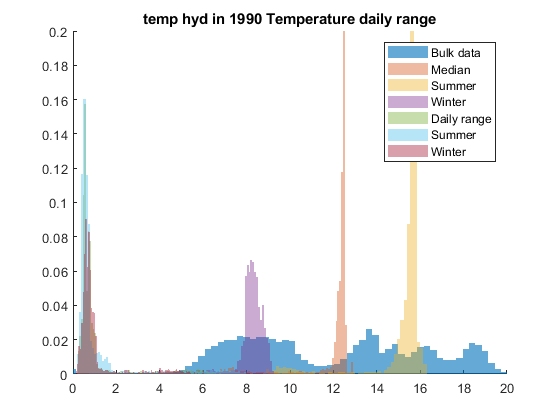

try load ([wdworknc,etudenc,'_Hyd_TEMP_',anstr],'Hyd_TEMP');
figure;clf;
hold on; 
x=eval(['nc2d.' nc2d.predict{6,1} '_' anstr]);
xs=eval(['nc2d.' nc2d.predict{6,1} '_s' '_' anstr]);
xw=eval(['nc2d.' nc2d.predict{6,1} '_w' '_' anstr]);
x1=eval(['nc2d.' nc2d.predict{7,1} '_' anstr]);
x1s=eval(['nc2d.' nc2d.predict{7,1} '_s' '_' anstr]);
x1w=eval(['nc2d.' nc2d.predict{7,1} '_w' '_' anstr]);
histogram(Hyd_TEMP,finesse,'EdgeColor','none','Normalization','probability');
title(sprintf('%s in %s %s','temp hyd', anstr, nc2d.predict{7,2}));
histogram(x,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xs,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xw,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1s,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1w,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
legend('Bulk data','Median','Summer','Winter','Daily range','Summer','Winter')
xlim([0 20]); ylim([0 0.2]);
hold off
if save_plot==true; print(sprintf('%s%s_Insp_temp_hyd_%s', wdgraph,etude,anstr),'-dtiff',plot_reso); end
clear Hyd_TEMP
catch e
    fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
end % try à partir de base

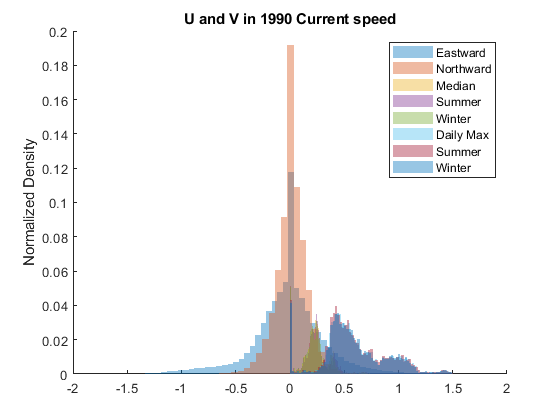

try load ([wdworknc,etudenc,'_Hyd_UZ_',anstr],'Hyd_UZ');
    load ([wdworknc,etudenc,'_Hyd_VZ_',anstr],'Hyd_VZ');
figure;clf;
hold on;
x=eval(['nc2d.' nc2d.predict{1,1} '_' anstr]);
xs=eval(['nc2d.' nc2d.predict{1,1} '_s' '_' anstr]);
xw=eval(['nc2d.' nc2d.predict{1,1} '_w' '_' anstr]);
x1=eval(['nc2d.' nc2d.predict{2,1} '_' anstr]);
x1s=eval(['nc2d.' nc2d.predict{2,1} '_s' '_' anstr]);
x1w=eval(['nc2d.' nc2d.predict{2,1} '_w' '_' anstr]);
histogram(Hyd_UZ,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability'); %,'FaceColor',!vecteur couleur in [0 1]
title(sprintf('%s in %s %s','U and V', anstr, nc2d.predict{1,2}));
histogram(Hyd_VZ,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability'); %,'FaceColor',!vecteur couleur in [0 1]
histogram(x,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xs,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xw,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1s,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(x1w,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
ylabel('Normalized Density');
legend('Eastward','Northward','Median','Summer','Winter','Daily Max','Summer','Winter')
xlim([-2 2]);
hold off
if save_plot==true; print(sprintf('%s%s_Insp_flow_%s', wdgraph,etude,anstr),'-dtiff',plot_reso); end
clear Hyd_UZ Hyd_VZ
catch e
    fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
end % try à partir de base

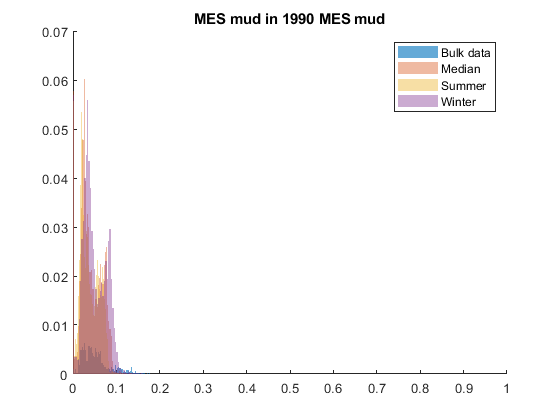

try load ([wdworknc,etudenc,'_Hyd_MES_mud_',anstr], 'Hyd_MES_mud');
figure;clf;
hold on; 
x=eval(['nc2d.' nc2d.predict{8,1} '_' anstr]);
xs=eval(['nc2d.' nc2d.predict{8,1} '_s' '_' anstr]);
xw=eval(['nc2d.' nc2d.predict{8,1} '_w' '_' anstr]);
histogram(Hyd_MES_mud(:,:,1,:),finesse*10,'EdgeColor','none','Normalization','probability');
title(sprintf('%s in %s %s','MES mud', anstr, nc2d.predict{8,2}));
histogram(x,finesse/2,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xs,finesse/2,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xw,finesse/2,'facealpha',.4,'EdgeColor','none','Normalization','probability');
legend('Bulk data','Median','Summer','Winter')
xlim([0 1]);
hold off
if save_plot==true; print(sprintf('%s%s_Insp_MES_mud_%s', wdgraph,etude,anstr),'-dtiff',plot_reso); end
clear Hyd_MES_mud
catch e
    fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
end % try à partir de base

### Variables Sediments 4D

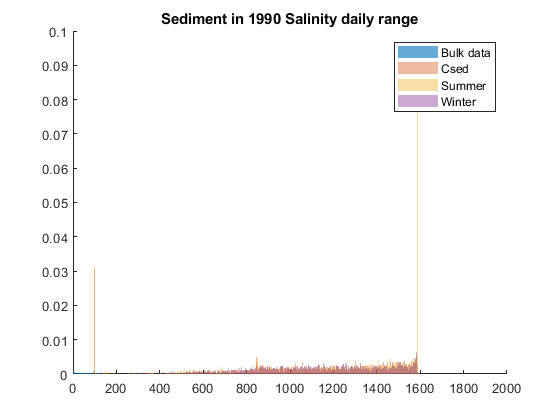

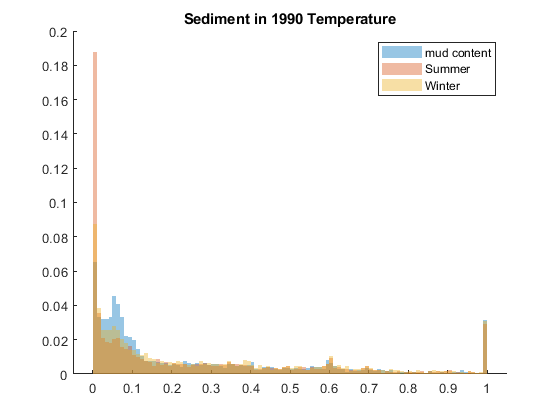

try load ([wdworknc,etudenc,'_Sed_MES_mud_',anstr],'Sed_MES_mud');
figure;clf;
hold on;
x=eval(['nc2d.' nc2d.predict{13,1} '_' anstr]);
xs=eval(['nc2d.' nc2d.predict{13,1} '_s' '_' anstr]);
xw=eval(['nc2d.' nc2d.predict{13,1} '_w' '_' anstr]);
histogram(Sed_MES_mud,finesse*100,'EdgeColor','none','Normalization','probability');
title(sprintf('%s in %s %s','Sediment', anstr, nc2d.predict{5,2}));
histogram(x,finesse*5,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xs,finesse*5,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xw,finesse*5,'facealpha',.4,'EdgeColor','none','Normalization','probability');
legend('Bulk data','Csed','Summer','Winter')
xlim([0 2000]); ylim([0 0.1]); 
hold off
if save_plot==true; print(sprintf('%s%s_Insp_Csed_%s', wdgraph,etude,anstr),'-dtiff',plot_reso); end
clf;

hold on;
x=eval(['nc2d.' nc2d.predict{14,1} '_' anstr]);
xs=eval(['nc2d.' nc2d.predict{14,1} '_s' '_' anstr]);
xw=eval(['nc2d.' nc2d.predict{14,1} '_w' '_' anstr]);
title(sprintf('%s in %s %s','Sediment', anstr, nc2d.predict{6,2}));
histogram(x,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xs,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
histogram(xw,finesse,'facealpha',.4,'EdgeColor','none','Normalization','probability');
legend('mud content','Summer','Winter')
hold off
if save_plot==true; print(sprintf('%s%s_Insp_Mud_content_%s', wdgraph,etude,anstr),'-dtiff',plot_reso); end
clear Sed_MES_mud
catch e
    fprintf(2,'There was an error Line %d! The message was:\n%s',e.stack(1).line,e.message);
end % try à partir de base

## Fin de la boucle

end
toc
load gong.mat; sound(y);% beep

Elapsed time is 88.402962 seconds.
